clear; clc; close all;

nfft = 128;
M = 16;
ofdm_symbols = 50;
snr = 23;
%multipath = [1 0.1 0.3 0.3];
multipath = [0 0 1];
%multipath = [1 0.4 0.3];
%multipath = 1;
cpo = 0;

cp_len = nfft/4;
rep = 4;
pilot_index = [4:rep:nfft-5,nfft-5];
pilot_carriers = length(pilot_index);
zp_index = [1:3,nfft-4:nfft];
zp_carriers = length(zp_index);


**Transmit:**

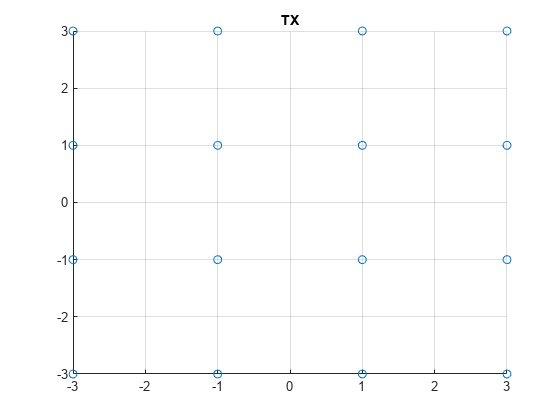

rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);
P = qammod(pilot_data,M);
%pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:4-1);
%P = qammod(pilot_data,4);
% P = [];
% for i = 1:ofdm_symbols
%     P(:,i) = zadoffChuSeq(1,pilot_carriers+1);
% end
% P(end,:) = [];
%pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:2-1);
%P = pskmod(pilot_data,2);
rng default
tx_data = randsrc(nfft,ofdm_symbols,0:M-1);
X = qammod(tx_data,M);
tx_data([pilot_index,zp_index],:) = [];
X(pilot_index,:) = P;

figure(),scatter(real(X),imag(X)),title('TX'),grid on

X(zp_index,:) = 0+0j;

x_pre_cp = ifft(X,nfft);
cp = x_pre_cp(nfft-cp_len+1:end,:);
x = vertcat(cp,x_pre_cp);

x = reshape(x,[(nfft+cp_len)*ofdm_symbols 1]);

**Channel:**

x_channel = awgn(x,snr,'measured');
%%%%%%%%%%%%% Demod with only SNR
x_rx_snr = reshape(x_channel,[nfft+cp_len ofdm_symbols]);
x_rx_snr = x_rx_snr(cp_len+1:end,:);
X_RX_snr = fft(x_rx_snr,nfft);
X_RX_pilot = X_RX_snr(pilot_index,:);
%X_RX_snr = X_RX_snr(pilot_index,:);
%x_channel = exp(-1i*cpo)*x_channel;

x_channel = filter(multipath,1,x_channel);

%%%%%%%%%%%% Find true channel H
H_true = fft(multipath,nfft);

**Demodulate:**

x_channel = reshape(x_channel,[nfft+cp_len ofdm_symbols]);
x_rx = x_channel(cp_len+1:end,:);
for i = 1:ofdm_symbols
    x_rx(:,i) = x_rx(:,i)*exp(-1j*0.6*i);
end
X_RX = fft(x_rx,nfft);
P_RX = X_RX(pilot_index,:);
%X_RX(pilot_index,:) = [];
H = conj(P_RX) ./ conj(P);
H_ZF = conj(H) ./ abs(H .* H);

Z_EQ = X_RX; Z_EQ2 = X_RX; Z_EQ3 = X_RX; Z_EQ4 = X_RX; Z_EQ5 = X_RX; Z_EQ6 = X_RX; Z_EQ7 = X_RX;
H_ZF2 = H_ZF; H_ZF3 = H_ZF;
H_tmp_ZF = P_RX ./ P;
H_ZF_interp = interp1(pilot_index,H_tmp_ZF,1:nfft,'spline');
H_ZF_interp(isnan(H_ZF_interp))=0;
% Normal ZF
% for i=1:ofdm_symbols
%     for k=1:pilot_carriers
%         index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
%         %Z_EQ(index,i) = X_RX(index,i) * conj(H_ZF(k,i));
%         Z_EQ(index,i) = X_RX(index,i) / H_tmp_ZF(k,i);
%     end
% end
for i = 1:ofdm_symbols
    for k = 1:nfft
        Z_EQ(k,i) = X_RX(k,i) / H_ZF_interp(k,i);
    end
end
% ZF with 1 interpolation point
for i=1:ofdm_symbols
    for k=1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
        if (k ~= pilot_carriers)
            H_ZF2(k,i) = (H_ZF(k,i) + H_ZF(k+1,i))/2;
        end
        Z_EQ2(index,i) = X_RX(index,i) * conj(H_ZF2(k,i));
    end
end
% ZF with 3 interpolation points
% for i=1:ofdm_symbols
%     for k=1:length(pilot_index)
%         index = ((rep-1)*(k-1)+1:(rep-1)*k);
%         if (k ~= 8)
%             h_tmp2 = (H_ZF(k,i)+H_ZF(k+1,i))/2;
%             h_tmp3 = (h_tmp2+H_ZF(k+1,i))/2;
%             h_tmp1 = (H_ZF(k,i)+h_tmp2)/2;
%             H_tmp = [h_tmp1; h_tmp2; h_tmp3];
%         end
%         Z_EQ3(index,i) = X_RX(index,i) .* conj(H_tmp);
%     end
% end
% ZF phase only averaged accross 1 symbol
H_P = mean(H);
for i=1:ofdm_symbols
    Z_EQ3(:,i) = X_RX(:,i) * exp(1j*angle(H_P(i)));
end
P_RX2 = Z_EQ3(pilot_index,:);
H2 = conj(P_RX2) ./ conj(P);
H_ZF2 = conj(H2) ./ abs(H2 .* H2);
num_taps = 4;
% Stage 1 4-tap ZF equalizer
H_est = X_RX;
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
        if (k~=pilot_carriers) && (i~=ofdm_symbols-2) && (i~=ofdm_symbols-1) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i) H_ZF2(k,i+1) H_ZF2(k+1,i+1) H_ZF2(k,i+2) H_ZF2(k+1,i+2) H_ZF2(k,i+3) H_ZF2(k+1,i+3)]);
        elseif (k~=pilot_carriers) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i) H_ZF2(k,i+1) H_ZF2(k+1,i+1)]);
        elseif (k~=pilot_carriers)
            H_tmp = mean([H_ZF2(k,i) H_ZF2(k+1,i)]);
        end
        H_est(index,i) = ones(1,length(index))*H_tmp;
        Z_EQ4(index,i) = Z_EQ3(index,i) .* conj(H_tmp);
        %Z_EQ4(index,i) = Z_EQ3(index,i) .* conj(H_ZF2(k,i));
    end
end
% 3rd Stage ZF equalizer
P_RX3 = Z_EQ4(pilot_index,:);
H3 = conj(P_RX3) ./ conj(P);
H_ZF3 = conj(H3) ./ abs(H3 .* H3);
%H_ZF3 = H_ZF3*exp(1j*pi/4);
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
        %Z_EQ6(index,i) = Z_EQ4(index,i) .* exp(1j*angle(H_ZF3(k,i)));
        Z_EQ6(index,i) = Z_EQ4(index,i) .* (H3(k,i));
    end
end
H3 = P_RX3 ./ P;
noise = mean(mean(H3));
noise = noise * conj(noise)

noise = 0.7950

noise = 0;
H_MMSE = conj(H3) ./ ((conj(H3) .* H3) + noise);
freq_avg = 3;
time_avg = 4;
H_est_avg = X_RX;
H_ZF_save = zeros(pilot_carriers,ofdm_symbols);
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
        ind_lo = k-floor(freq_avg/2);
        ind_hi = k+floor(freq_avg/2);
        if ind_lo < 1
            ind_lo = 1;
        end
        if ind_hi > pilot_carriers
            ind_hi = pilot_carriers;
        end
        i_lo = i-floor(freq_avg/2);
        i_hi = i+floor(freq_avg/2);
        if i_lo < 1
            i_lo = 1;
        end
        if i_hi > ofdm_symbols
            i_hi = ofdm_symbols;
        end
        H_tmp = mean(mean(H_ZF2(ind_lo:ind_hi,i_lo:i_hi)));
        H_ZF_save(k,i) = conj(H_tmp);
        H_est_avg(index,i) = ones(1,length(index))*H_tmp;
        Z_EQ7(index,i) = Z_EQ3(index,i) * conj(H_tmp);
    end
end
H_ZF2_interp = interp1(pilot_index,H_ZF_save,1:nfft,'spline');
Z_EQ8 = Z_EQ3 .* H_ZF2_interp;
% Stage 1 4-tap ZF equalizer
for i = 1:ofdm_symbols
    for k = 1:pilot_carriers
        index = ((rep)*(k-1)+1:(rep)*k) + zp_index(end/2-1);
        if (k~=pilot_carriers) && (i~=ofdm_symbols-2) && (i~=ofdm_symbols-1) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1) H_ZF(k,i+2) H_ZF(k+1,i+2) H_ZF(k,i+3) H_ZF(k+1,i+3)]);
        elseif (k~=pilot_carriers) && (i ~= ofdm_symbols)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i) H_ZF(k,i+1) H_ZF(k+1,i+1)]);
        elseif (k~=pilot_carriers)
            H_tmp = mean([H_ZF(k,i) H_ZF(k+1,i)]);
        end
        Z_EQ5(index,i) = X_RX(index,i) .* conj(H_tmp);
    end
end

% AWGN only ideal channel compare to equalizer
X_RX_snr([pilot_index,zp_index],:) = [];
% AWGN + channel
X_RX([pilot_index,zp_index],:) = [];
% Normal ZF
Z_EQ([pilot_index,zp_index],:) = [];
% ZF with Averaging across 2 SC in frequency
Z_EQ2([pilot_index,zp_index],:) = [];
% Phase only ZF (Average phase across entire symbol applied)
Z_EQ3([pilot_index,zp_index],:) = [];
% 2nd stage (after phase averaged ZF), ZF averaged across 2 SC's and 4 symbols
Z_EQ4([pilot_index,zp_index],:) = [];
% ZF equalizer averaging pilot estimates across 2 pilot locations and 4 symbols
Z_EQ5([pilot_index,zp_index],:) = [];
% 3rd Stage equalizer
Z_EQ6([pilot_index,zp_index],:) = [];
Z_EQ7([pilot_index,zp_index],:) = [];
Z_EQ8([pilot_index,zp_index],:) = [];

rx = qamdemod(X_RX_snr,M);
no_eq = qamdemod(X_RX,M);
zf_eq = qamdemod(Z_EQ,M);
zf_eq_1_interp = qamdemod(Z_EQ2,M);
zf_eq_1_interp_4_tap = qamdemod(Z_EQ5,M);
zf_eq_2_stage = qamdemod(Z_EQ4,M);
zf_eq_2_stage2 = qamdemod(Z_EQ7,M);
zf_eq_2_stage3 = qamdemod(Z_EQ8,M);

rx_ser = symerr(tx_data,rx)/numel(tx_data);
no_eq_ser = symerr(tx_data,no_eq)/numel(tx_data);
zf_eq_ser = symerr(tx_data,zf_eq)/numel(tx_data);
zf_eq_1_interp_ser = symerr(tx_data,zf_eq_1_interp)/numel(tx_data);
zf_eq_1_interp_4_tap_ser = symerr(tx_data,zf_eq_1_interp_4_tap)/numel(tx_data);
zf_eq_2_stage_ser = symerr(tx_data,zf_eq_2_stage)/numel(tx_data);
zf_eq_2_stage2_ser = symerr(tx_data,zf_eq_2_stage2)/numel(tx_data);
zf_eq_2_stage3_ser = symerr(tx_data,zf_eq_2_stage3)/numel(tx_data);

X_tx = X;
X([pilot_index,zp_index],:) = [];
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[rx_evm,rx_pk] = evm(X,X_RX_snr);
[no_eq_evm,no_eq_pk] = evm(X,X_RX);
[zf_eq_evm,zf_eq_pk] = evm(X,Z_EQ) ;
[zf_eq_1_interp_evm,zf_eq_1_interp_pk] = evm(X,Z_EQ2);
[zf_eq_1_interp_4_tap_evm,zf_eq_1_interp_4_tap_pk] = evm(X,Z_EQ3);
[zf_eq_2_stage_evm,zf_eq_2_stage_pk] = evm(X,Z_EQ4);
[zf_eq_2_stage2_evm,zf_eq_2_stage2_pk] = evm(X,Z_EQ7);
[zf_eq_2_stage3_evm,zf_eq_2_stage3_pk] = evm(X,Z_EQ8);

Equalization = ["AWGN";"No Equalization";"ZF";"Interpolated ZF";"4-Tap Interpolated ZF";"2-Stage ZF";"2-Stage ZF Method 2";"2-Stage ZF Method 3"];
SER = [rx_ser;no_eq_ser;zf_eq_ser;zf_eq_1_interp_ser;zf_eq_1_interp_4_tap_ser;zf_eq_2_stage_ser;zf_eq_2_stage2_ser;zf_eq_2_stage3_ser];
AverageEVM = [rx_evm;no_eq_evm;zf_eq_evm;zf_eq_1_interp_evm;zf_eq_1_interp_4_tap_evm;zf_eq_2_stage_evm;zf_eq_2_stage2_evm;zf_eq_2_stage3_evm];
PeakEvm = [rx_pk;no_eq_pk;zf_eq_pk;zf_eq_1_interp_pk;zf_eq_1_interp_4_tap_pk;zf_eq_2_stage_pk;zf_eq_2_stage2_pk;zf_eq_2_stage3_pk];

table(Equalization,SER,AverageEVM,PeakEvm)

ans = 8×4 table
         Equalization             SER        AverageEVM    PeakEvm
    _______________________    __________    __________    _______

    "AWGN"                              0      6.7873      23.493 
    "No Equalization"             0.85978      140.93      278.19 
    "ZF"                       0.00067416      11.174      52.172 
    "Interpolated ZF"           0.0013483      12.684      47.093 
    "4-Tap Interpolated ZF"       0.90584      136.31      275.57 
    "2-Stage ZF"                  0.26809      33.068      114.36 
    "2-Stage ZF Method 2"         0.29978      34.747      110.61 
    "2-Stage ZF Method 3"         0.22854      28.398      80.583 


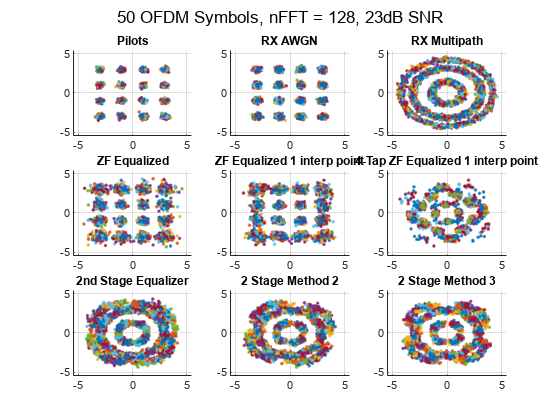


%y_lim = [-2 2]; x_lim = [-2 2];
lim = sqrt(M) + 1.5;
y_lim = [-lim lim]; x_lim = [-lim lim]; 
%y_lim = [-5 5]; x_lim = [-5 5]; % 16 QAM
%ylim = [-7 7]; x_lim = [-7 7]; % 32 QAM
%y_lim = [-9 9]; x_lim = [-9 9]; % 64 QAM
%y_lim = [-15 15]; x_lim = [-15 15]; % 128 QAM
%y_lim = [-19 19]; x_lim = [-19 19]; % 256 QAM
figure(),subplot(3,3,1),scatter(real(X_RX_pilot),imag(X_RX_pilot),'.','LineWidth',2),grid on,title('Pilots'),xlim(x_lim),ylim(y_lim)
subplot(3,3,2),scatter(real(X_RX_snr),imag(X_RX_snr),'.','LineWidth',2),grid on,title('RX AWGN'),xlim(x_lim),ylim(y_lim)
subplot(3,3,3),scatter(real(X_RX),imag(X_RX),'.','lineWidth',2),grid on,title('RX Multipath'),xlim(x_lim),ylim(y_lim)
subplot(3,3,4),scatter(real(Z_EQ),imag(Z_EQ),'.','lineWidth',2),grid on,title('ZF Equalized'),xlim(x_lim),ylim(y_lim)
subplot(3,3,5),scatter(real(Z_EQ2),imag(Z_EQ2),'.','lineWidth',2),grid on,title('ZF Equalized 1 interp point'),xlim(x_lim),ylim(y_lim)
subplot(3,3,6),scatter(real(Z_EQ5),imag(Z_EQ5),'.','lineWidth',2),grid on,title('4-Tap ZF Equalized 1 interp point'),xlim(x_lim),ylim(y_lim)
subplot(3,3,7),scatter(real(Z_EQ4),imag(Z_EQ4),'.','LineWidth',2),grid on,title('2nd Stage Equalizer'),xlim(x_lim),ylim(y_lim)
%subplot(3,2,6),scatter(real(Z_EQ6),imag(Z_EQ6),'.','LineWidth',2),grid on,title('3rd Stage Equalizer'),xlim(x_lim),ylim(y_lim)
subplot(3,3,8),scatter(real(Z_EQ7),imag(Z_EQ7),'.','LineWidth',2),grid on,title('2 Stage Method 2'),xlim(x_lim),ylim(y_lim)
subplot(3,3,9),scatter(real(Z_EQ8),imag(Z_EQ8),'.','LineWidth',2),grid on,title('2 Stage Method 3'),xlim(x_lim),ylim(y_lim)
sgtitle([num2str(ofdm_symbols),' OFDM Symbols, nFFT = ',num2str(nfft),', ',num2str(snr),'dB SNR'])

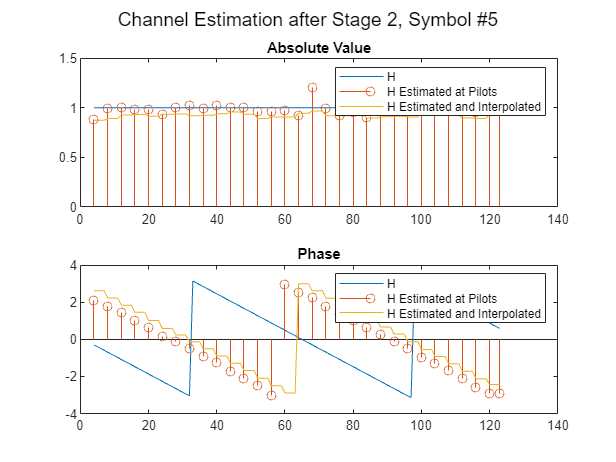

% Plot Channel estimation vs actual channel
symb = 5;
y1 = 1:nfft;
y1(zp_index) = [];
H_true_abs1 = abs(H_true);
H_true_abs1(zp_index) = [];
H_true_abs = (-1*(abs(H_true)-1))+1;
H_true_abs(zp_index) = [];
H_true_angle = angle(H_true);
H_true_angle(zp_index) = [];
H_est(zp_index,:) = [];
figure(),subplot(2,1,1),plot(y1,H_true_abs),hold on,stem(pilot_index,abs(H_ZF2(:,symb)))
plot(y1,abs(H_est(:,symb))),title('Absolute Value'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
subplot(2,1,2),plot(y1,H_true_angle),hold on,stem(pilot_index,angle(H_ZF2(:,symb)))
plot(y1,angle(H_est(:,symb))),title('Phase'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
sgtitle(['Channel Estimation after Stage 2, Symbol #',num2str(symb)])

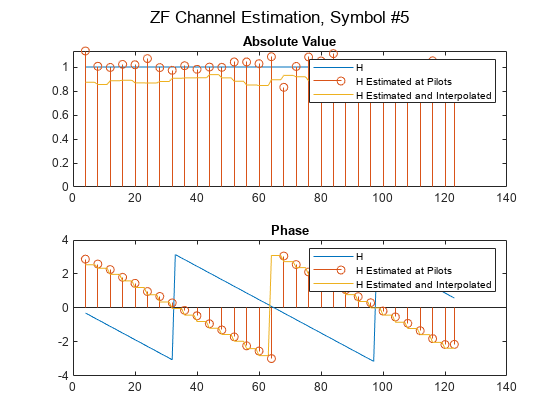

% figure(),subplot(2,1,1),plot(y1,H_true_abs),hold on,stem(pilot_index,abs(H_ZF3(:,symb)))
% title('Absolute Value'),legend('H','H Estimated at Pilots')
% subplot(2,1,2),plot(y1,H_true_angle),hold on,stem(pilot_index,angle(H_ZF3(:,symb)))
% title('Phase'),legend('H','H Estimated at Pilots')
% sgtitle(['Channel Estimation after Stage 3, Symbol #',num2str(symb)])
H_est_avg(zp_index,:) = [];
figure(),subplot(2,1,1),plot(y1,H_true_abs),hold on,stem(pilot_index,abs(H_tmp_ZF(:,symb)))
plot(y1,abs(H_est_avg(:,symb)))
title('Absolute Value'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
subplot(2,1,2),plot(y1,H_true_angle),hold on,stem(pilot_index,angle(H_tmp_ZF(:,symb)))
plot(y1,angle(H_est_avg(:,symb)))
title('Phase'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
sgtitle(['ZF Channel Estimation, Symbol #',num2str(symb)])

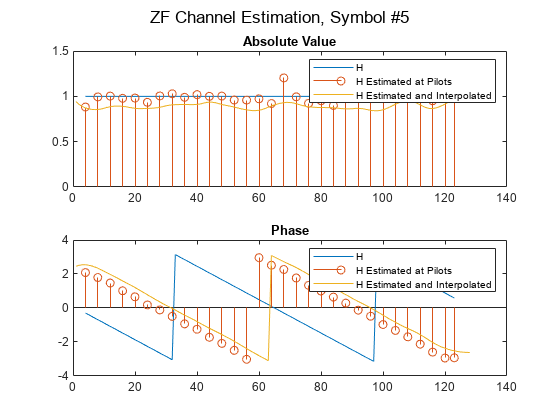

figure(),subplot(2,1,1),plot(y1,H_true_abs),hold on,stem(pilot_index,abs(H_ZF2(:,symb)))
plot(1:nfft,abs(H_ZF2_interp(:,symb)))
title('Absolute Value'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
subplot(2,1,2),plot(y1,H_true_angle),hold on,stem(pilot_index,angle(H_ZF2(:,symb)))
plot(1:nfft,angle(conj(H_ZF2_interp(:,symb))))
title('Phase'),legend('H','H Estimated at Pilots','H Estimated and Interpolated')
sgtitle(['ZF Channel Estimation, Symbol #',num2str(symb)])

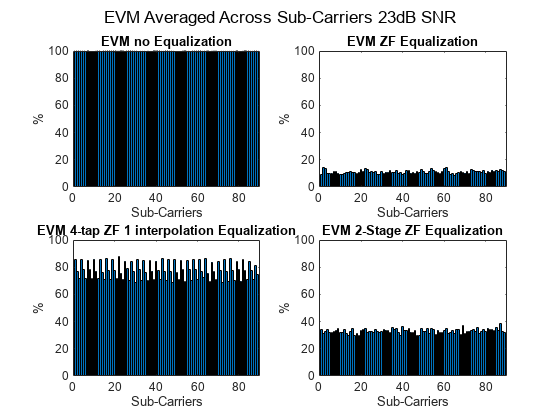

% Plot EVM vs Subcarriers 
evm = comm.EVM(AveragingDimensions=2);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ5);
zf_eq_2_stage_evm = evm(X,Z_EQ4);

y_lim = [0 100];
y = 1:nfft-zp_carriers-pilot_carriers;
figure(),subplot(2,2,1),bar(y,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,2),bar(y,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(y,zf_eq_1_interp_4_tap_evm),title('EVM 4-tap ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,4),bar(y,zf_eq_2_stage_evm),title('EVM 2-Stage ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
sgtitle(['EVM Averaged Across Sub-Carriers ',num2str(snr),'dB SNR'])

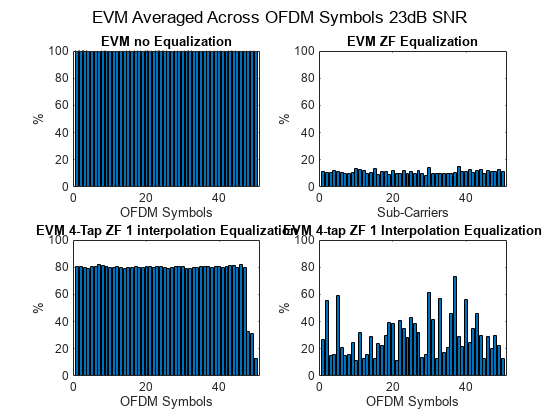

% Plot EVM vs OFDM Symbols
evm = comm.EVM(AveragingDimensions=1);
no_eq_evm = evm(X,X_RX);
zf_eq_evm = evm(X,Z_EQ) ;
zf_eq_1_interp_evm = evm(X,Z_EQ2);
zf_eq_1_interp_4_tap_evm = evm(X,Z_EQ5);
zf_eq_2_stage_evm = evm(X,Z_EQ4);

y_lim = [0 100];
figure(),subplot(2,2,1),bar(1:ofdm_symbols,no_eq_evm),title('EVM no Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,2),bar(1:ofdm_symbols,zf_eq_evm),title('EVM ZF Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('Sub-Carriers')
subplot(2,2,3),bar(1:ofdm_symbols,zf_eq_1_interp_4_tap_evm),title('EVM 4-Tap ZF 1 interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
subplot(2,2,4),bar(1:ofdm_symbols,zf_eq_2_stage_evm),title('EVM 4-tap ZF 1 Interpolation Equalization'),ax = gca;ax.YLim = y_lim;ylabel('%'),xlabel('OFDM Symbols')
sgtitle(['EVM Averaged Across OFDM Symbols ',num2str(snr),'dB SNR'])

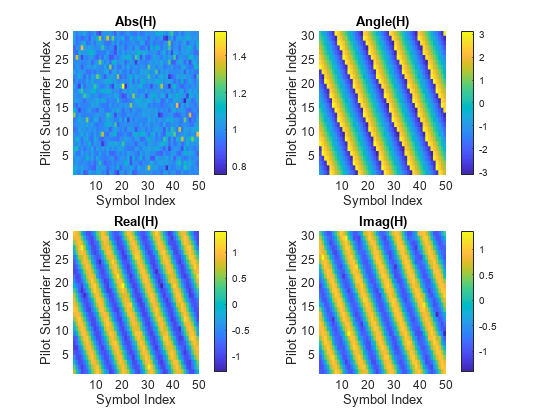

figure(),subplot(2,2,1),s = surf(abs(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Abs(H)')
subplot(2,2,2),s = surf(angle(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Angle(H)')
subplot(2,2,3),s = surf(real(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Real(H)')
subplot(2,2,4),s = surf(imag(H_ZF)); s.EdgeColor = 'none'; view(2); xlim([1 ofdm_symbols]); ylim([1 length(pilot_index)])
colorbar,xlabel('Symbol Index'),ylabel('Pilot Subcarrier Index'),title('Imag(H)')